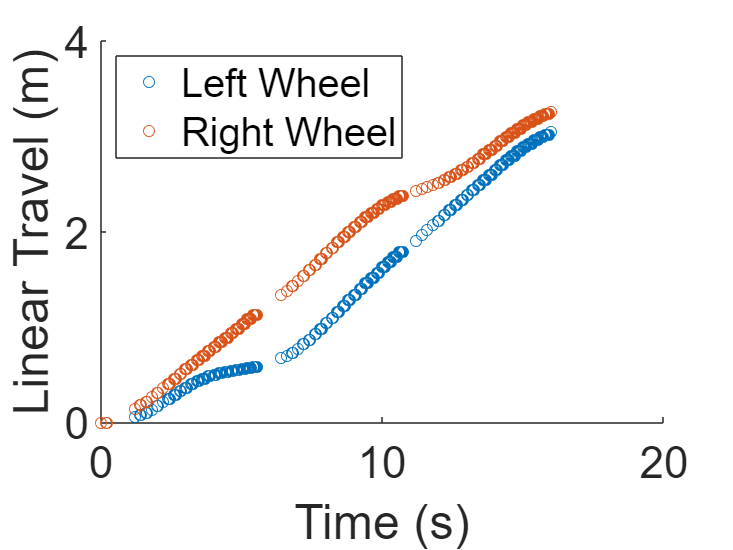

% Plot encoder data
figure()
scatter(encoder_data(:,1),encoder_data(:,2:3));
set(gca,'FontSize',24);
xlabel("Time (s)")
ylabel("Linear Travel (m)")
legend('Left Wheel','Right Wheel','Location','northwest');

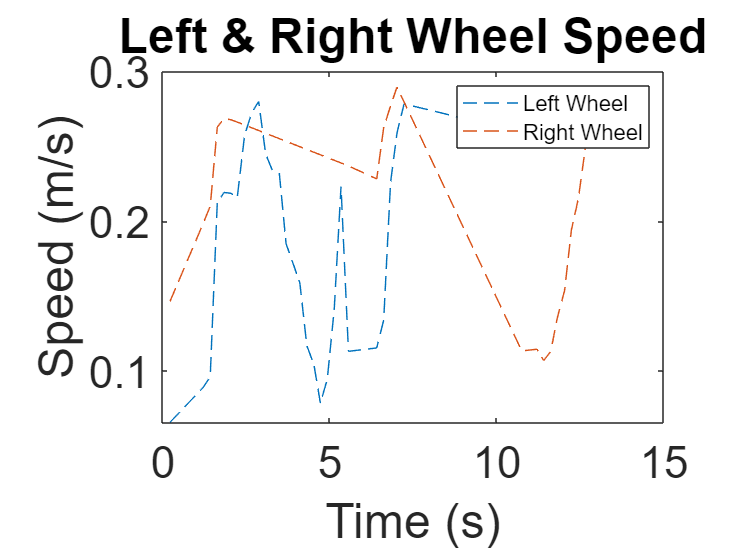

% Plot left/right wheel speed
encoder_diff = diff(encoder_data);
speeds = [encoder_diff(:,2)./encoder_diff(:,1), encoder_diff(:,3)./encoder_diff(:,1)];
left_new = [];
time_old = encoder_data(:,1);
time_new_left = [];
right_new = [];
time_new_right = [];

count = 1;
for i=1:length(speeds)
    if speeds(i,1) ~= 0 && speeds(i,1) <= 0.3 
        left_new(count,1) = speeds(i,1);
        time_new_left(count,1) = time_old(i);
        count = count + 1;
    end
end
count = 1;
for i=1:length(speeds)
    if speeds(i,2) ~= 0 && speeds(i,2) <= 0.3
        right_new(count,1) = speeds(i,2);
        time_new_right(count,1) = time_old(i);
        count = count + 1;
    end
end


figure()
plot(time_new_left, left_new, "--")
hold on
plot(time_new_right, right_new, "--")
set(gca, 'FontSize', 24);
xlabel("Time (s)");
ylabel("Speed (m/s)");
%axis([0 16 0 18]);
legend('Left Wheel','Right Wheel','fontsize',12);
title("Left & Right Wheel Speed")

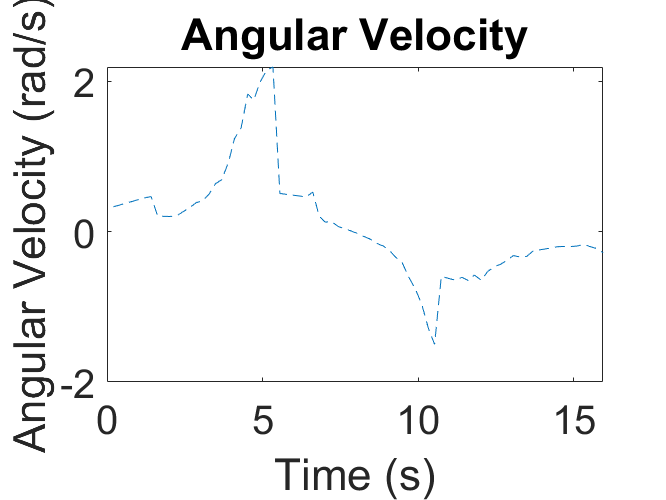

% Plot angular wheel speed
%rad_convert = 2*pi*(1/360);
ang_speed = ((speeds(:,2)-speeds(:,1))./0.245);
ang_speed_new = [];
time_old = encoder_data(:,1);
time_new = [];
count = 1;
for i=1:length(ang_speed)
    if ang_speed(i) ~= 0 
        ang_speed_new(count,1) = ang_speed(i);
        time_new(count,1) = time_old(i);
        count = count + 1;
    end
end

%ang_speed_rad = rad_convert*ang_speed_new;

figure()
plot(time_new, ang_speed_new,"--");
%axis([0 16 -20 22])
set(gca, 'FontSize', 24);
xlabel("Time (s)");
ylabel("Angular Velocity (rad/s)");
title("Angular Velocity")

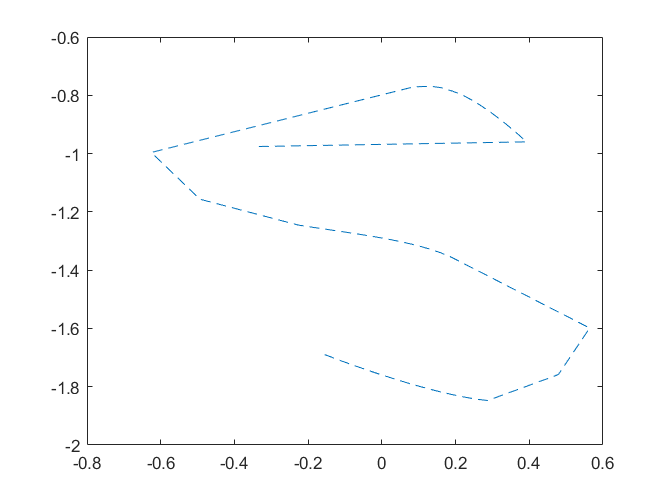

%Plot path

big_V = (sum(speeds, 2))/2;
big_V_current = big_V(1);
x_pos = -0.3337;
y_pos = -0.9756;
x_pos_list = [x_pos];
y_pos_list = [y_pos];
theta = 0;
for i = 2:length(time_old)-1
    big_V_current = big_V(i);
    delta_t = time_old(i) - time_old(i-1);
    delta_t = delta_t/0.2;
    x_pos = x_pos + big_V_current*cos(theta)*delta_t;
    y_pos = y_pos + big_V_current*sin(theta)*delta_t;
    theta = theta + ang_speed(i)*delta_t;
    x_pos_list(i, 1) = x_pos;
    y_pos_list(i,1) = y_pos;
end

figure()
plot(x_pos_list, y_pos_list, "--")

dxdt = diff(x_pos_list)./encoder_diff(1:end-1,1);
dydt = diff(y_pos_list)./encoder_diff(1:end-1,1);





